clc; clf; clear all;
% a) location of the end effector [x (cm), y(cm), z(cm)]
Endeffector = [0, ... 
               10, ...
               20 ];

% b)
% for elbow down, check the box
% for elbow up, uncheck the box
elbow_down = true

elbow_down = logical
   1


Shoulder_left = true

Shoulder_left = logical
   1



%c)
%call the inverse kinematics function
[q, reachability] =Anthropomorphic_inverse_function(Endeffector, elbow_down, Shoulder_left);
   %Q.No.4 reachability check
   if (reachability == 1)   
       fprintf('The destination is in reachable space.');
   else
       fprintf('The destination is out of reachable space.');
   end

The destination is in reachable space.

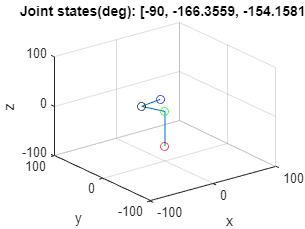

   %d
   % calls the forward kinematics function
   [base, Joint1, Joint2, Endeff] = Anthropomorphic_forward_function(q);
   %x, y and z coordinates
  %x, y and z coordinates
    xvar = [base(1) Joint1(1)  Joint2(1) Endeff(1)];
    yvar = [base(2) Joint1(2)  Joint2(2) Endeff(2)];
    zvar = [base(3) Joint1(3)  Joint2(3) Endeff(3)];

   %e
   %Draws the manipulator in the desired configuration
    plot3(xvar,yvar,zvar);
    grid on;
    ax = gca;
    ax.XAxisLocation = 'origin';            
    ax.YAxisLocation = 'origin'; 
    axis([-100 100 -100 100 -100 100]); 
    xlabel('x');
    ylabel('y');
    zlabel('z');
    hold on
    plot3(base(1),base(2), base(3), 'or', Joint1(1),Joint1(2), Joint1(3),...
    'og', Joint2(1),Joint2(2), Joint2(3), 'ok', Endeff(1), Endeff(2), ...
    Endeff(3), 'ob');
     title("End Effector wrt to frame 0:" + ...
    "("+Endeff(1)+ ","+Endeff(2)+ ","+Endeff(3)+ ")");
     title("Joint states(deg): ["+q(1)+ ", "+q(2)+ ", "+q(3)+"]"); 
     hold off

     
    %printing the joint coordinates
    base

base =      0
     0
   -70


    Joint1

Joint1 =      0
     0
     0


    Joint2

Joint2 =          0
   48.5890
  -11.7945


    Endeff

Endeff =          0
   10.0000
   20.0000
